clc
clear all
format long g
% Template for assignment 1, advanced part
% ----------------------------------------------
% INPUTS
% ------

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%55
NELEM = 60 ;  % Number of elements
nsteps = 61 ;  % Number of steps
stepsPOST = 1:12:nsteps; % Steps to post-process


A0 = 1e-2; %m  % Reference AREA
E0 = 10 ; % MPa  % Reference Young's Modulus
sigma_0 = 1; %MPa  % Saturation stress
L = 1 ;%m    % Length of the beam
T = 1; % s Final time
um = 0.2*L; %m   % Maximum displacement
AreaFUN = @(x) (A0*(1+2*(x/L).*(x/L-1)))  ;  % Area as a function of the distance from the left end
stressFUN = @(strain) (sigma_0*(1-exp(-E0/sigma_0*strain))) ;  % Constitutive equation (stress versus strain)
DerStressFUN = @(strain) (E0*exp(-E0/sigma_0*strain)) ;  % Tangent modulus (Derivative of the stress with respect to the strain)
r = [1,NELEM+1]  ; % Indexes Prescribed DOF  %
uEND = @(t) (t/T*um);  %  Non-zero prescribed displacement, as a function of time
TOL_residual = 1e-6;  % Convergence tolerance for the Newton-Raphson
MAXITER = 50 ;  % Maximum number of iterations  for the Newton-Raphson
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%% END INPUTS % ------------------------------------------
% MESH INFORMATION
nnode = NELEM+1 ;
COOR = linspace(0,L,nnode)' ;
CN = [(1:(nnode-1))',(2:nnode)'] ;
l = setdiff([1:nnode],r) ;

d = zeros(nnode,1) ;  % Displacement at time tn

TIMES = linspace(0,T,nsteps) ;

% STORE INFORMATION for post-processing purpose
% -----------------------
STRESS_GLO = zeros(NELEM,nsteps) ;
STRAIN_GLO  = zeros(NELEM,nsteps) ;
d_GLO  = zeros(nnode,length(stepsPOST)) ;

iplot = 1;



for istep=1:nsteps
    t = TIMES(istep) ;  % Time
    d(nnode) = uEND(t) ;    
    
    disp(['Number of  step = ',num2str(istep), ', Time = ',num2str(t),', uEND =  ',num2str( uEND(t)) ])
    disp('********************************************************************')
    % Boundary conditions
    %-------------------
    % Compute the vector of internal forces = residual
    % as a function of the nodal displacement n
    
    % Solution of the equations Residual(d) = 0     via Newton-Raphson
    % algoritm
    d_k = d; %   nodal displacements at iteration k
    k = 0 ; % Number of iteration
    while  k <= MAXITER
        % ASsembly the residual vector (= internal forces)
        [Residual,STRAIN,STRESS] = AssemblyFint(COOR,CN,d_k,stressFUN,AreaFUN) ;
        normRESIDUAL = norm(Residual(l)) ; % Euclidean norm residual
        disp(['k = ',num2str(k),' res=',num2str(normRESIDUAL),', MAX strain = ',num2str(max(STRAIN)),', MAX stress = ',num2str(max(STRESS))])
        if normRESIDUAL < TOL_residual
            % Convergence
            d = d_k ;
            break
        end
        % The norm of the residual is greater than the prescribed
        % tolerance.  This means that equilibrium is not met
        % Let us calculate the new displacement vector
        
        % Compute the Jacobian of the system of equations
        K = AssemblyKnon(COOR,CN,d_k,AreaFUN,DerStressFUN);
            Delta_d_l = -K(l,l)\Residual(l) ;
        d_k(l) = d_k(l) + Delta_d_l;
        k = k +1 ;
    end
    
    if  k >  MAXITER
        error('The Newtown-R. algorithm has failed to converge')
    else
        d=d_k ;
        d_GLO(:,iplot) = d ;
        STRAIN_GLO(:,iplot) = STRAIN ;
        STRESS_GLO(:,iplot) = STRESS ;
        iplot = iplot +1 ;
    end
end

Number of  step = 1, Time = 0, uEND =  0


********************************************************************


k = 0 res=0, MAX strain = 0, MAX stress = 0


Number of  step = 2, Time = 0.016667, uEND =  0.0033333


********************************************************************


k = 0 res=0.0085037, MAX strain = 0.2, MAX stress = 0.86466
k = 1 res=0.48279, MAX strain = 0.01268, MAX stress = 0.11909
k = 2 res=0.17514, MAX strain = 0.010677, MAX stress = 0.10127
k = 3 res=0.061995, MAX strain = 0.0086036, MAX stress = 0.082439
k = 4 res=0.020505, MAX strain = 0.0067193, MAX stress = 0.064985
k = 5 res=0.0056138, MAX strain = 0.0052445, MAX stress = 0.051093
k = 6 res=0.00090866, MAX strain = 0.0044519, MAX stress = 0.043542
k = 7 res=3.7382e-05, MAX strain = 0.0042676, MAX stress = 0.041779
k = 8 res=7.0672e-08, MAX strain = 0.0042594, MAX stress = 0.0417


Number of  step = 3, Time = 0.033333, uEND =  0.0066667


********************************************************************


k = 0 res=0.0083234, MAX strain = 0.20214, MAX stress = 0.86753
k = 1 res=0.47538, MAX strain = 0.01705, MAX stress = 0.15675
k = 2 res=0.17246, MAX strain = 0.015035, MAX stress = 0.13959
k = 3 res=0.061062, MAX strain = 0.012943, MAX stress = 0.12141
k = 4 res=0.020209, MAX strain = 0.011042, MAX stress = 0.10454
k = 5 res=0.0055423, MAX strain = 0.0095524, MAX stress = 0.091103
k = 6 res=0.00090144, MAX strain = 0.0087492, MAX stress = 0.083774
k = 7 res=3.7531e-05, MAX strain = 0.0085613, MAX stress = 0.08205
k = 8 res=7.2772e-08, MAX strain = 0.0085527, MAX stress = 0.081972


Number of  step = 4, Time = 0.05, uEND =  0.01


********************************************************************


k = 0 res=0.0081492, MAX strain = 0.20426, MAX stress = 0.87031
k = 1 res=0.46829, MAX strain = 0.021458, MAX stress = 0.19312
k = 2 res=0.1699, MAX strain = 0.019431, MAX stress = 0.17659
k = 3 res=0.060168, MAX strain = 0.01732, MAX stress = 0.15903
k = 4 res=0.019926, MAX strain = 0.015402, MAX stress = 0.14274
k = 5 res=0.0054743, MAX strain = 0.013896, MAX stress = 0.12974
k = 6 res=0.00089476, MAX strain = 0.013082, MAX stress = 0.12263
k = 7 res=3.7709e-05, MAX strain = 0.01289, MAX stress = 0.12094
k = 8 res=7.5026e-08, MAX strain = 0.012881, MAX stress = 0.12086


Number of  step = 5, Time = 0.066667, uEND =  0.013333


********************************************************************


k = 0 res=0.0079811, MAX strain = 0.20634, MAX stress = 0.87298
k = 1 res=0.46148, MAX strain = 0.025906, MAX stress = 0.22822
k = 2 res=0.16744, MAX strain = 0.023866, MAX stress = 0.21231
k = 3 res=0.059311, MAX strain = 0.021736, MAX stress = 0.19536
k = 4 res=0.019654, MAX strain = 0.019799, MAX stress = 0.17962
k = 5 res=0.0054093, MAX strain = 0.018278, MAX stress = 0.16704
k = 6 res=0.00088854, MAX strain = 0.017452, MAX stress = 0.16014
k = 7 res=3.7911e-05, MAX strain = 0.017256, MAX stress = 0.15849
k = 8 res=7.7419e-08, MAX strain = 0.017247, MAX stress = 0.15842


Number of  step = 6, Time = 0.083333, uEND =  0.016667


********************************************************************


k = 0 res=0.0078187, MAX strain = 0.2084, MAX stress = 0.87557
k = 1 res=0.45494, MAX strain = 0.030395, MAX stress = 0.26211
k = 2 res=0.16509, MAX strain = 0.028342, MAX stress = 0.24679
k = 3 res=0.058488, MAX strain = 0.026192, MAX stress = 0.23043
k = 4 res=0.019394, MAX strain = 0.024236, MAX stress = 0.21523
k = 5 res=0.0053474, MAX strain = 0.022698, MAX stress = 0.20306
k = 6 res=0.00088278, MAX strain = 0.02186, MAX stress = 0.19636
k = 7 res=3.8137e-05, MAX strain = 0.02166, MAX stress = 0.19475
k = 8 res=7.9958e-08, MAX strain = 0.021651, MAX stress = 0.19467


Number of  step = 7, Time = 0.1, uEND =  0.02


********************************************************************


k = 0 res=0.0076619, MAX strain = 0.21042, MAX stress = 0.87806
k = 1 res=0.44867, MAX strain = 0.034928, MAX stress = 0.29481
k = 2 res=0.16282, MAX strain = 0.032861, MAX stress = 0.28007
k = 3 res=0.0577, MAX strain = 0.03069, MAX stress = 0.26428
k = 4 res=0.019145, MAX strain = 0.028714, MAX stress = 0.24959
k = 5 res=0.0052883, MAX strain = 0.027158, MAX stress = 0.23783
k = 6 res=0.00087745, MAX strain = 0.026309, MAX stress = 0.23132
k = 7 res=3.8386e-05, MAX strain = 0.026104, MAX stress = 0.22975
k = 8 res=8.2652e-08, MAX strain = 0.026094, MAX stress = 0.22967


Number of  step = 8, Time = 0.11667, uEND =  0.023333


********************************************************************


k = 0 res=0.0075105, MAX strain = 0.21242, MAX stress = 0.88047
k = 1 res=0.44267, MAX strain = 0.039506, MAX stress = 0.32636
k = 2 res=0.16066, MAX strain = 0.037424, MAX stress = 0.31219
k = 3 res=0.056946, MAX strain = 0.035232, MAX stress = 0.29694
k = 4 res=0.018907, MAX strain = 0.033235, MAX stress = 0.28277
k = 5 res=0.0052321, MAX strain = 0.031661, MAX stress = 0.27139
k = 6 res=0.00087256, MAX strain = 0.030799, MAX stress = 0.26507
k = 7 res=3.8659e-05, MAX strain = 0.030589, MAX stress = 0.26354
k = 8 res=8.5508e-08, MAX strain = 0.030579, MAX stress = 0.26346


Number of  step = 9, Time = 0.13333, uEND =  0.026667


********************************************************************


k = 0 res=0.0073644, MAX strain = 0.21438, MAX stress = 0.8828
k = 1 res=0.43692, MAX strain = 0.044131, MAX stress = 0.35681
k = 2 res=0.15858, MAX strain = 0.042034, MAX stress = 0.34318
k = 3 res=0.056224, MAX strain = 0.039819, MAX stress = 0.32846
k = 4 res=0.018679, MAX strain = 0.037801, MAX stress = 0.31478
k = 5 res=0.0051787, MAX strain = 0.036208, MAX stress = 0.30377
k = 6 res=0.00086809, MAX strain = 0.035332, MAX stress = 0.29765
k = 7 res=3.8956e-05, MAX strain = 0.035118, MAX stress = 0.29614
k = 8 res=8.8535e-08, MAX strain = 0.035108, MAX stress = 0.29607


Number of  step = 10, Time = 0.15, uEND =  0.03


********************************************************************


k = 0 res=0.0072234, MAX strain = 0.21632, MAX stress = 0.88504
k = 1 res=0.43142, MAX strain = 0.048805, MAX stress = 0.38618
k = 2 res=0.1566, MAX strain = 0.046693, MAX stress = 0.37307
k = 3 res=0.055533, MAX strain = 0.044453, MAX stress = 0.35888
k = 4 res=0.018462, MAX strain = 0.042413, MAX stress = 0.34566
k = 5 res=0.0051279, MAX strain = 0.0408, MAX stress = 0.33502
k = 6 res=0.00086404, MAX strain = 0.039911, MAX stress = 0.32908
k = 7 res=3.9277e-05, MAX strain = 0.039692, MAX stress = 0.32761
k = 8 res=9.1743e-08, MAX strain = 0.039681, MAX stress = 0.32754


Number of  step = 11, Time = 0.16667, uEND =  0.033333


********************************************************************


k = 0 res=0.0070873, MAX strain = 0.21822, MAX stress = 0.88721
k = 1 res=0.42615, MAX strain = 0.05353, MAX stress = 0.41451
k = 2 res=0.1547, MAX strain = 0.051402, MAX stress = 0.40191
k = 3 res=0.054873, MAX strain = 0.049137, MAX stress = 0.38822
k = 4 res=0.018254, MAX strain = 0.047074, MAX stress = 0.37546
k = 5 res=0.0050798, MAX strain = 0.045441, MAX stress = 0.36518
k = 6 res=0.00086039, MAX strain = 0.044537, MAX stress = 0.35941
k = 7 res=3.9622e-05, MAX strain = 0.044313, MAX stress = 0.35798
k = 8 res=9.5141e-08, MAX strain = 0.044302, MAX stress = 0.3579


Number of  step = 12, Time = 0.18333, uEND =  0.036667


********************************************************************


k = 0 res=0.006956, MAX strain = 0.22009, MAX stress = 0.8893
k = 1 res=0.42112, MAX strain = 0.058309, MAX stress = 0.44183
k = 2 res=0.15289, MAX strain = 0.056163, MAX stress = 0.42972
k = 3 res=0.054242, MAX strain = 0.053873, MAX stress = 0.41651
k = 4 res=0.018056, MAX strain = 0.051786, MAX stress = 0.4042
k = 5 res=0.0050342, MAX strain = 0.050131, MAX stress = 0.39426
k = 6 res=0.00085715, MAX strain = 0.049212, MAX stress = 0.38867
k = 7 res=3.9992e-05, MAX strain = 0.048983, MAX stress = 0.38727
k = 8 res=9.8739e-08, MAX strain = 0.048971, MAX stress = 0.3872


Number of  step = 13, Time = 0.2, uEND =  0.04


********************************************************************


k = 0 res=0.0068293, MAX strain = 0.22193, MAX stress = 0.89131
k = 1 res=0.41632, MAX strain = 0.063143, MAX stress = 0.46817
k = 2 res=0.15116, MAX strain = 0.06098, MAX stress = 0.45654
k = 3 res=0.053641, MAX strain = 0.058663, MAX stress = 0.4438
k = 4 res=0.017868, MAX strain = 0.05655, MAX stress = 0.43192
k = 5 res=0.0049911, MAX strain = 0.054873, MAX stress = 0.42232
k = 6 res=0.0008543, MAX strain = 0.053939, MAX stress = 0.41689
k = 7 res=4.0387e-05, MAX strain = 0.053704, MAX stress = 0.41552
k = 8 res=1.0255e-07, MAX strain = 0.053691, MAX stress = 0.41545


Number of  step = 14, Time = 0.21667, uEND =  0.043333


********************************************************************


k = 0 res=0.0067071, MAX strain = 0.22373, MAX stress = 0.89326
k = 1 res=0.41174, MAX strain = 0.068035, MAX stress = 0.49356
k = 2 res=0.14951, MAX strain = 0.065855, MAX stress = 0.4824
k = 3 res=0.053068, MAX strain = 0.063509, MAX stress = 0.47011
k = 4 res=0.017689, MAX strain = 0.06137, MAX stress = 0.45865
k = 5 res=0.0049505, MAX strain = 0.05967, MAX stress = 0.44937
k = 6 res=0.00085184, MAX strain = 0.058719, MAX stress = 0.44411
k = 7 res=4.0808e-05, MAX strain = 0.058478, MAX stress = 0.44277
k = 8 res=1.0658e-07, MAX strain = 0.058465, MAX stress = 0.4427


Number of  step = 15, Time = 0.23333, uEND =  0.046667


********************************************************************


k = 0 res=0.0065892, MAX strain = 0.22551, MAX stress = 0.89513
k = 1 res=0.40738, MAX strain = 0.072989, MAX stress = 0.51804
k = 2 res=0.14794, MAX strain = 0.070789, MAX stress = 0.50732
k = 3 res=0.052522, MAX strain = 0.068414, MAX stress = 0.49548
k = 4 res=0.017519, MAX strain = 0.066247, MAX stress = 0.48442
k = 5 res=0.0049122, MAX strain = 0.064523, MAX stress = 0.47546
k = 6 res=0.00084975, MAX strain = 0.063555, MAX stress = 0.47036
k = 7 res=4.1253e-05, MAX strain = 0.063308, MAX stress = 0.46905
k = 8 res=1.1085e-07, MAX strain = 0.063295, MAX stress = 0.46898


Number of  step = 16, Time = 0.25, uEND =  0.05


********************************************************************


k = 0 res=0.0064756, MAX strain = 0.22724, MAX stress = 0.89694
k = 1 res=0.40322, MAX strain = 0.078005, MAX stress = 0.54162
k = 2 res=0.14644, MAX strain = 0.075787, MAX stress = 0.53133
k = 3 res=0.052003, MAX strain = 0.07338, MAX stress = 0.51992
k = 4 res=0.017357, MAX strain = 0.071184, MAX stress = 0.50926
k = 5 res=0.0048763, MAX strain = 0.069435, MAX stress = 0.5006
k = 6 res=0.00084804, MAX strain = 0.06845, MAX stress = 0.49566
k = 7 res=4.1724e-05, MAX strain = 0.068197, MAX stress = 0.49438
k = 8 res=1.1536e-07, MAX strain = 0.068183, MAX stress = 0.49431


Number of  step = 17, Time = 0.26667, uEND =  0.053333


********************************************************************


k = 0 res=0.0063661, MAX strain = 0.22895, MAX stress = 0.89868
k = 1 res=0.39927, MAX strain = 0.083089, MAX stress = 0.56434
k = 2 res=0.14502, MAX strain = 0.08085, MAX stress = 0.55447
k = 3 res=0.05151, MAX strain = 0.078411, MAX stress = 0.54348
k = 4 res=0.017204, MAX strain = 0.076185, MAX stress = 0.5332
k = 5 res=0.0048426, MAX strain = 0.074409, MAX stress = 0.52484
k = 6 res=0.00084669, MAX strain = 0.073406, MAX stress = 0.52004
k = 7 res=4.2221e-05, MAX strain = 0.073146, MAX stress = 0.5188
k = 8 res=1.2013e-07, MAX strain = 0.073132, MAX stress = 0.51873


Number of  step = 18, Time = 0.28333, uEND =  0.056667


********************************************************************


k = 0 res=0.0062605, MAX strain = 0.23062, MAX stress = 0.90036
k = 1 res=0.39552, MAX strain = 0.088242, MAX stress = 0.58622
k = 2 res=0.14367, MAX strain = 0.085982, MAX stress = 0.57676
k = 3 res=0.051042, MAX strain = 0.083509, MAX stress = 0.56617
k = 4 res=0.01706, MAX strain = 0.081252, MAX stress = 0.55626
k = 5 res=0.0048111, MAX strain = 0.079449, MAX stress = 0.54819
k = 6 res=0.00084571, MAX strain = 0.078426, MAX stress = 0.54354
k = 7 res=4.2744e-05, MAX strain = 0.078159, MAX stress = 0.54232
k = 8 res=1.2517e-07, MAX strain = 0.078144, MAX stress = 0.54226


Number of  step = 19, Time = 0.3, uEND =  0.06


********************************************************************


k = 0 res=0.0061587, MAX strain = 0.23226, MAX stress = 0.90198
k = 1 res=0.39196, MAX strain = 0.093468, MAX stress = 0.60729
k = 2 res=0.14238, MAX strain = 0.091186, MAX stress = 0.59823
k = 3 res=0.0506, MAX strain = 0.088678, MAX stress = 0.58802
k = 4 res=0.016923, MAX strain = 0.086387, MAX stress = 0.57847
k = 5 res=0.0047818, MAX strain = 0.084556, MAX stress = 0.57068
k = 6 res=0.00084508, MAX strain = 0.083514, MAX stress = 0.56618
k = 7 res=4.3293e-05, MAX strain = 0.083239, MAX stress = 0.56499
k = 8 res=1.305e-07, MAX strain = 0.083224, MAX stress = 0.56492


Number of  step = 20, Time = 0.31667, uEND =  0.063333


********************************************************************


k = 0 res=0.0060607, MAX strain = 0.23387, MAX stress = 0.90354
k = 1 res=0.38859, MAX strain = 0.09877, MAX stress = 0.62757
k = 2 res=0.14117, MAX strain = 0.096466, MAX stress = 0.61889
k = 3 res=0.050181, MAX strain = 0.093921, MAX stress = 0.60906
k = 4 res=0.016795, MAX strain = 0.091595, MAX stress = 0.59987
k = 5 res=0.0047546, MAX strain = 0.089734, MAX stress = 0.59235
k = 6 res=0.0008448, MAX strain = 0.088671, MAX stress = 0.58799
k = 7 res=4.3868e-05, MAX strain = 0.088389, MAX stress = 0.58683
k = 8 res=1.3613e-07, MAX strain = 0.088373, MAX stress = 0.58676


Number of  step = 21, Time = 0.33333, uEND =  0.066667


********************************************************************


k = 0 res=0.0059663, MAX strain = 0.23544, MAX stress = 0.90505
k = 1 res=0.3854, MAX strain = 0.10415, MAX stress = 0.64709
k = 2 res=0.14003, MAX strain = 0.10183, MAX stress = 0.63878
k = 3 res=0.049785, MAX strain = 0.099241, MAX stress = 0.62932
k = 4 res=0.016674, MAX strain = 0.096879, MAX stress = 0.62046
k = 5 res=0.0047294, MAX strain = 0.094986, MAX stress = 0.61321
k = 6 res=0.00084486, MAX strain = 0.093902, MAX stress = 0.60899
k = 7 res=4.4471e-05, MAX strain = 0.093612, MAX stress = 0.60785
k = 8 res=1.4208e-07, MAX strain = 0.093595, MAX stress = 0.60779


Number of  step = 22, Time = 0.35, uEND =  0.07


********************************************************************


k = 0 res=0.0058753, MAX strain = 0.23697, MAX stress = 0.90649
k = 1 res=0.38239, MAX strain = 0.10962, MAX stress = 0.66586
k = 2 res=0.13895, MAX strain = 0.10727, MAX stress = 0.65791
k = 3 res=0.049413, MAX strain = 0.10464, MAX stress = 0.64881
k = 4 res=0.01656, MAX strain = 0.10224, MAX stress = 0.64028
k = 5 res=0.0047063, MAX strain = 0.10032, MAX stress = 0.63328
k = 6 res=0.00084525, MAX strain = 0.09921, MAX stress = 0.6292
k = 7 res=4.51e-05, MAX strain = 0.098911, MAX stress = 0.62809
k = 8 res=1.4835e-07, MAX strain = 0.098894, MAX stress = 0.62803


Number of  step = 23, Time = 0.36667, uEND =  0.073333


********************************************************************


k = 0 res=0.0057878, MAX strain = 0.23847, MAX stress = 0.90789
k = 1 res=0.37956, MAX strain = 0.11518, MAX stress = 0.68392
k = 2 res=0.13793, MAX strain = 0.1128, MAX stress = 0.67631
k = 3 res=0.049063, MAX strain = 0.11013, MAX stress = 0.66756
k = 4 res=0.016454, MAX strain = 0.10769, MAX stress = 0.65935
k = 5 res=0.0046851, MAX strain = 0.10573, MAX stress = 0.65261
k = 6 res=0.00084598, MAX strain = 0.1046, MAX stress = 0.64865
k = 7 res=4.5757e-05, MAX strain = 0.10429, MAX stress = 0.64757
k = 8 res=1.5497e-07, MAX strain = 0.10427, MAX stress = 0.64751


Number of  step = 24, Time = 0.38333, uEND =  0.076667


********************************************************************


k = 0 res=0.0057036, MAX strain = 0.23994, MAX stress = 0.90923
k = 1 res=0.3769, MAX strain = 0.12082, MAX stress = 0.70128
k = 2 res=0.13697, MAX strain = 0.11842, MAX stress = 0.69401
k = 3 res=0.048734, MAX strain = 0.11571, MAX stress = 0.68559
k = 4 res=0.016355, MAX strain = 0.11322, MAX stress = 0.67769
k = 5 res=0.0046659, MAX strain = 0.11123, MAX stress = 0.67119
k = 6 res=0.00084704, MAX strain = 0.11007, MAX stress = 0.66737
k = 7 res=4.6441e-05, MAX strain = 0.10976, MAX stress = 0.66632
k = 8 res=1.6195e-07, MAX strain = 0.10974, MAX stress = 0.66625


Number of  step = 25, Time = 0.4, uEND =  0.08


********************************************************************


k = 0 res=0.0056225, MAX strain = 0.24137, MAX stress = 0.91052
k = 1 res=0.3744, MAX strain = 0.12657, MAX stress = 0.71796
k = 2 res=0.13607, MAX strain = 0.12414, MAX stress = 0.71102
k = 3 res=0.048427, MAX strain = 0.12138, MAX stress = 0.70292
k = 4 res=0.016263, MAX strain = 0.11885, MAX stress = 0.69533
k = 5 res=0.0046485, MAX strain = 0.11682, MAX stress = 0.68906
k = 6 res=0.00084842, MAX strain = 0.11564, MAX stress = 0.68537
k = 7 res=4.7153e-05, MAX strain = 0.11531, MAX stress = 0.68434
k = 8 res=1.6932e-07, MAX strain = 0.11529, MAX stress = 0.68428


Number of  step = 26, Time = 0.41667, uEND =  0.083333


********************************************************************


k = 0 res=0.0055445, MAX strain = 0.24277, MAX stress = 0.91176
k = 1 res=0.37206, MAX strain = 0.13242, MAX stress = 0.73398
k = 2 res=0.13524, MAX strain = 0.12996, MAX stress = 0.72736
k = 3 res=0.04814, MAX strain = 0.12715, MAX stress = 0.71958
k = 4 res=0.016177, MAX strain = 0.12458, MAX stress = 0.71228
k = 5 res=0.004633, MAX strain = 0.1225, MAX stress = 0.70625
k = 6 res=0.00085011, MAX strain = 0.12129, MAX stress = 0.70267
k = 7 res=4.7892e-05, MAX strain = 0.12096, MAX stress = 0.70167
k = 8 res=1.7707e-07, MAX strain = 0.12094, MAX stress = 0.70161


Number of  step = 27, Time = 0.43333, uEND =  0.086667


********************************************************************


k = 0 res=0.0054696, MAX strain = 0.24413, MAX stress = 0.91295
k = 1 res=0.36988, MAX strain = 0.13838, MAX stress = 0.74937
k = 2 res=0.13446, MAX strain = 0.13589, MAX stress = 0.74305
k = 3 res=0.047874, MAX strain = 0.13302, MAX stress = 0.73558
k = 4 res=0.016099, MAX strain = 0.1304, MAX stress = 0.72856
k = 5 res=0.0046192, MAX strain = 0.12829, MAX stress = 0.72276
k = 6 res=0.00085212, MAX strain = 0.12705, MAX stress = 0.7193
k = 7 res=4.866e-05, MAX strain = 0.1267, MAX stress = 0.71833
k = 8 res=1.8525e-07, MAX strain = 0.12668, MAX stress = 0.71827


Number of  step = 28, Time = 0.45, uEND =  0.09


********************************************************************


k = 0 res=0.0053976, MAX strain = 0.24545, MAX stress = 0.9141
k = 1 res=0.36786, MAX strain = 0.14445, MAX stress = 0.76413
k = 2 res=0.13373, MAX strain = 0.14193, MAX stress = 0.75812
k = 3 res=0.047627, MAX strain = 0.13901, MAX stress = 0.75094
k = 4 res=0.016026, MAX strain = 0.13634, MAX stress = 0.7442
k = 5 res=0.0046072, MAX strain = 0.13418, MAX stress = 0.73861
k = 6 res=0.00085443, MAX strain = 0.13291, MAX stress = 0.73528
k = 7 res=4.9455e-05, MAX strain = 0.13255, MAX stress = 0.73433
k = 8 res=1.9385e-07, MAX strain = 0.13253, MAX stress = 0.73427


Number of  step = 29, Time = 0.46667, uEND =  0.093333


********************************************************************


k = 0 res=0.0053283, MAX strain = 0.24674, MAX stress = 0.9152
k = 1 res=0.36598, MAX strain = 0.15064, MAX stress = 0.7783
k = 2 res=0.13306, MAX strain = 0.14809, MAX stress = 0.77257
k = 3 res=0.0474, MAX strain = 0.14511, MAX stress = 0.76569
k = 4 res=0.01596, MAX strain = 0.14238, MAX stress = 0.75921
k = 5 res=0.004597, MAX strain = 0.14018, MAX stress = 0.75384
k = 6 res=0.00085705, MAX strain = 0.13888, MAX stress = 0.75062
k = 7 res=5.0279e-05, MAX strain = 0.13851, MAX stress = 0.7497
k = 8 res=2.029e-07, MAX strain = 0.13848, MAX stress = 0.74964


Number of  step = 30, Time = 0.48333, uEND =  0.096667


********************************************************************


k = 0 res=0.0052619, MAX strain = 0.248, MAX stress = 0.91625
k = 1 res=0.36425, MAX strain = 0.15696, MAX stress = 0.79188
k = 2 res=0.13244, MAX strain = 0.15438, MAX stress = 0.78643
k = 3 res=0.047191, MAX strain = 0.15134, MAX stress = 0.77983
k = 4 res=0.015901, MAX strain = 0.14855, MAX stress = 0.77362
k = 5 res=0.0045884, MAX strain = 0.1463, MAX stress = 0.76845
k = 6 res=0.00085996, MAX strain = 0.14496, MAX stress = 0.76534
k = 7 res=5.1132e-05, MAX strain = 0.14458, MAX stress = 0.76445
k = 8 res=2.1242e-07, MAX strain = 0.14456, MAX stress = 0.76439


Number of  step = 31, Time = 0.5, uEND =  0.1


********************************************************************


k = 0 res=0.0051981, MAX strain = 0.24922, MAX stress = 0.91727
k = 1 res=0.36267, MAX strain = 0.16342, MAX stress = 0.80489
k = 2 res=0.13188, MAX strain = 0.1608, MAX stress = 0.79972
k = 3 res=0.047, MAX strain = 0.15769, MAX stress = 0.79339
k = 4 res=0.015847, MAX strain = 0.15485, MAX stress = 0.78743
k = 5 res=0.0045815, MAX strain = 0.15254, MAX stress = 0.78246
k = 6 res=0.00086317, MAX strain = 0.15117, MAX stress = 0.77947
k = 7 res=5.2013e-05, MAX strain = 0.15078, MAX stress = 0.7786
k = 8 res=2.2243e-07, MAX strain = 0.15075, MAX stress = 0.77854


Number of  step = 32, Time = 0.51667, uEND =  0.10333


********************************************************************


k = 0 res=0.0051369, MAX strain = 0.2504, MAX stress = 0.91824
k = 1 res=0.36122, MAX strain = 0.17002, MAX stress = 0.81735
k = 2 res=0.13136, MAX strain = 0.16737, MAX stress = 0.81244
k = 3 res=0.046828, MAX strain = 0.16419, MAX stress = 0.80638
k = 4 res=0.015799, MAX strain = 0.16128, MAX stress = 0.80066
k = 5 res=0.0045761, MAX strain = 0.15891, MAX stress = 0.7959
k = 6 res=0.00086667, MAX strain = 0.15751, MAX stress = 0.79301
k = 7 res=5.2922e-05, MAX strain = 0.1571, MAX stress = 0.79216
k = 8 res=2.3295e-07, MAX strain = 0.15707, MAX stress = 0.79211


Number of  step = 33, Time = 0.53333, uEND =  0.10667


********************************************************************


k = 0 res=0.0050782, MAX strain = 0.25155, MAX stress = 0.91918
k = 1 res=0.35991, MAX strain = 0.17677, MAX stress = 0.82928
k = 2 res=0.1309, MAX strain = 0.17408, MAX stress = 0.82462
k = 3 res=0.046673, MAX strain = 0.17083, MAX stress = 0.81882
k = 4 res=0.015757, MAX strain = 0.16785, MAX stress = 0.81334
k = 5 res=0.0045724, MAX strain = 0.16543, MAX stress = 0.80877
k = 6 res=0.00087045, MAX strain = 0.16398, MAX stress = 0.80599
k = 7 res=5.3861e-05, MAX strain = 0.16356, MAX stress = 0.80517
k = 8 res=2.4399e-07, MAX strain = 0.16353, MAX stress = 0.80511


Number of  step = 34, Time = 0.55, uEND =  0.11


********************************************************************


k = 0 res=0.005022, MAX strain = 0.25266, MAX stress = 0.92007
k = 1 res=0.35874, MAX strain = 0.18369, MAX stress = 0.84068
k = 2 res=0.13048, MAX strain = 0.18096, MAX stress = 0.83628
k = 3 res=0.046535, MAX strain = 0.17762, MAX stress = 0.83072
k = 4 res=0.015721, MAX strain = 0.17457, MAX stress = 0.82548
k = 5 res=0.0045702, MAX strain = 0.17209, MAX stress = 0.8211
k = 6 res=0.0008745, MAX strain = 0.17061, MAX stress = 0.81842
k = 7 res=5.4828e-05, MAX strain = 0.17017, MAX stress = 0.81762
k = 8 res=2.5557e-07, MAX strain = 0.17014, MAX stress = 0.81756


Number of  step = 35, Time = 0.56667, uEND =  0.11333


********************************************************************


k = 0 res=0.0049681, MAX strain = 0.25374, MAX stress = 0.92093
k = 1 res=0.35769, MAX strain = 0.19077, MAX stress = 0.85158
k = 2 res=0.13011, MAX strain = 0.188, MAX stress = 0.84742
k = 3 res=0.046413, MAX strain = 0.18458, MAX stress = 0.84211
k = 4 res=0.01569, MAX strain = 0.18146, MAX stress = 0.83709
k = 5 res=0.0045695, MAX strain = 0.17891, MAX stress = 0.83289
k = 6 res=0.00087884, MAX strain = 0.17738, MAX stress = 0.83031
k = 7 res=5.5825e-05, MAX strain = 0.17693, MAX stress = 0.82954
k = 8 res=2.6772e-07, MAX strain = 0.17689, MAX stress = 0.82948


Number of  step = 36, Time = 0.58333, uEND =  0.11667


********************************************************************


k = 0 res=0.0049166, MAX strain = 0.25478, MAX stress = 0.92175
k = 1 res=0.35677, MAX strain = 0.19804, MAX stress = 0.86199
k = 2 res=0.12979, MAX strain = 0.19523, MAX stress = 0.85806
k = 3 res=0.046308, MAX strain = 0.19172, MAX stress = 0.85298
k = 4 res=0.015664, MAX strain = 0.18851, MAX stress = 0.84819
k = 5 res=0.0045703, MAX strain = 0.1859, MAX stress = 0.84417
k = 6 res=0.00088344, MAX strain = 0.18432, MAX stress = 0.84169
k = 7 res=5.685e-05, MAX strain = 0.18385, MAX stress = 0.84094
k = 8 res=2.8045e-07, MAX strain = 0.18381, MAX stress = 0.84089


Number of  step = 37, Time = 0.6, uEND =  0.12


********************************************************************


k = 0 res=0.0048673, MAX strain = 0.25579, MAX stress = 0.92253
k = 1 res=0.35598, MAX strain = 0.20551, MAX stress = 0.87192
k = 2 res=0.12951, MAX strain = 0.20266, MAX stress = 0.86821
k = 3 res=0.046219, MAX strain = 0.19905, MAX stress = 0.86337
k = 4 res=0.015644, MAX strain = 0.19575, MAX stress = 0.85879
k = 5 res=0.0045726, MAX strain = 0.19306, MAX stress = 0.85494
k = 6 res=0.00088832, MAX strain = 0.19144, MAX stress = 0.85256
k = 7 res=5.7904e-05, MAX strain = 0.19095, MAX stress = 0.85184
k = 8 res=2.9378e-07, MAX strain = 0.19091, MAX stress = 0.85179


Number of  step = 38, Time = 0.61667, uEND =  0.12333


********************************************************************


k = 0 res=0.0048201, MAX strain = 0.25676, MAX stress = 0.92328
k = 1 res=0.35531, MAX strain = 0.21318, MAX stress = 0.88138
k = 2 res=0.12927, MAX strain = 0.21029, MAX stress = 0.8779
k = 3 res=0.046146, MAX strain = 0.20657, MAX stress = 0.87328
k = 4 res=0.015629, MAX strain = 0.20319, MAX stress = 0.86891
k = 5 res=0.0045762, MAX strain = 0.20042, MAX stress = 0.86523
k = 6 res=0.00089345, MAX strain = 0.19874, MAX stress = 0.86295
k = 7 res=5.8986e-05, MAX strain = 0.19823, MAX stress = 0.86225
k = 8 res=3.0773e-07, MAX strain = 0.19819, MAX stress = 0.86219


Number of  step = 39, Time = 0.63333, uEND =  0.12667


********************************************************************


k = 0 res=0.0047751, MAX strain = 0.2577, MAX stress = 0.924
k = 1 res=0.35475, MAX strain = 0.22108, MAX stress = 0.89039
k = 2 res=0.12908, MAX strain = 0.21814, MAX stress = 0.88712
k = 3 res=0.046088, MAX strain = 0.21432, MAX stress = 0.88272
k = 4 res=0.015619, MAX strain = 0.21083, MAX stress = 0.87855
k = 5 res=0.0045813, MAX strain = 0.20798, MAX stress = 0.87504
k = 6 res=0.00089884, MAX strain = 0.20624, MAX stress = 0.87285
k = 7 res=6.0098e-05, MAX strain = 0.20571, MAX stress = 0.87218
k = 8 res=3.2233e-07, MAX strain = 0.20567, MAX stress = 0.87212


Number of  step = 40, Time = 0.65, uEND =  0.13


********************************************************************


k = 0 res=0.0047322, MAX strain = 0.25861, MAX stress = 0.92468
k = 1 res=0.35431, MAX strain = 0.22923, MAX stress = 0.89896
k = 2 res=0.12893, MAX strain = 0.22624, MAX stress = 0.8959
k = 3 res=0.046044, MAX strain = 0.22229, MAX stress = 0.89171
k = 4 res=0.015614, MAX strain = 0.2187, MAX stress = 0.88774
k = 5 res=0.0045877, MAX strain = 0.21575, MAX stress = 0.88439
k = 6 res=0.00090449, MAX strain = 0.21396, MAX stress = 0.8823
k = 7 res=6.1238e-05, MAX strain = 0.2134, MAX stress = 0.88164
k = 8 res=3.3757e-07, MAX strain = 0.21336, MAX stress = 0.88159


Number of  step = 41, Time = 0.66667, uEND =  0.13333


********************************************************************


k = 0 res=0.0046912, MAX strain = 0.25947, MAX stress = 0.92533
k = 1 res=0.35399, MAX strain = 0.23763, MAX stress = 0.9071
k = 2 res=0.12882, MAX strain = 0.23459, MAX stress = 0.90424
k = 3 res=0.046015, MAX strain = 0.23052, MAX stress = 0.90026
k = 4 res=0.015613, MAX strain = 0.2268, MAX stress = 0.89649
k = 5 res=0.0045955, MAX strain = 0.22376, MAX stress = 0.89329
k = 6 res=0.00091039, MAX strain = 0.22191, MAX stress = 0.89129
k = 7 res=6.2407e-05, MAX strain = 0.22133, MAX stress = 0.89066
k = 8 res=3.535e-07, MAX strain = 0.22128, MAX stress = 0.89061


Number of  step = 42, Time = 0.68333, uEND =  0.13667


********************************************************************


k = 0 res=0.0046522, MAX strain = 0.26031, MAX stress = 0.92596
k = 1 res=0.35377, MAX strain = 0.24631, MAX stress = 0.91483
k = 2 res=0.12876, MAX strain = 0.24323, MAX stress = 0.91216
k = 3 res=0.046, MAX strain = 0.23901, MAX stress = 0.90838
k = 4 res=0.015618, MAX strain = 0.23517, MAX stress = 0.90479
k = 5 res=0.0046046, MAX strain = 0.23203, MAX stress = 0.90175
k = 6 res=0.00091653, MAX strain = 0.2301, MAX stress = 0.89984
k = 7 res=6.3604e-05, MAX strain = 0.2295, MAX stress = 0.89923
k = 8 res=3.7011e-07, MAX strain = 0.22945, MAX stress = 0.89919


Number of  step = 43, Time = 0.7, uEND =  0.14


********************************************************************


k = 0 res=0.0046151, MAX strain = 0.26111, MAX stress = 0.92655
k = 1 res=0.35366, MAX strain = 0.2553, MAX stress = 0.92215
k = 2 res=0.12873, MAX strain = 0.25216, MAX stress = 0.91967
k = 3 res=0.046, MAX strain = 0.24779, MAX stress = 0.91608
k = 4 res=0.015627, MAX strain = 0.24382, MAX stress = 0.91268
k = 5 res=0.004615, MAX strain = 0.24056, MAX stress = 0.90979
k = 6 res=0.00092291, MAX strain = 0.23856, MAX stress = 0.90797
k = 7 res=6.4829e-05, MAX strain = 0.23793, MAX stress = 0.90738
k = 8 res=3.8743e-07, MAX strain = 0.23788, MAX stress = 0.90734


Number of  step = 44, Time = 0.71667, uEND =  0.14333


********************************************************************


k = 0 res=0.0045799, MAX strain = 0.26187, MAX stress = 0.92711
k = 1 res=0.35366, MAX strain = 0.26461, MAX stress = 0.92907
k = 2 res=0.12874, MAX strain = 0.26143, MAX stress = 0.92678
k = 3 res=0.046013, MAX strain = 0.25689, MAX stress = 0.92338
k = 4 res=0.01564, MAX strain = 0.25277, MAX stress = 0.92016
k = 5 res=0.0046266, MAX strain = 0.24939, MAX stress = 0.91741
k = 6 res=0.00092954, MAX strain = 0.24731, MAX stress = 0.91568
k = 7 res=6.6082e-05, MAX strain = 0.24665, MAX stress = 0.91512
k = 8 res=4.0548e-07, MAX strain = 0.24659, MAX stress = 0.91507


Number of  step = 45, Time = 0.73333, uEND =  0.14667


********************************************************************


k = 0 res=0.0045464, MAX strain = 0.26261, MAX stress = 0.92764
k = 1 res=0.35376, MAX strain = 0.27429, MAX stress = 0.93561
k = 2 res=0.12878, MAX strain = 0.27105, MAX stress = 0.9335
k = 3 res=0.046039, MAX strain = 0.26633, MAX stress = 0.93028
k = 4 res=0.015658, MAX strain = 0.26205, MAX stress = 0.92724
k = 5 res=0.0046394, MAX strain = 0.25854, MAX stress = 0.92463
k = 6 res=0.00093639, MAX strain = 0.25637, MAX stress = 0.92298
k = 7 res=6.7363e-05, MAX strain = 0.25568, MAX stress = 0.92245
k = 8 res=4.2427e-07, MAX strain = 0.25562, MAX stress = 0.9224


Number of  step = 46, Time = 0.75, uEND =  0.15


********************************************************************


k = 0 res=0.0045147, MAX strain = 0.26331, MAX stress = 0.92814
k = 1 res=0.35397, MAX strain = 0.28435, MAX stress = 0.94178
k = 2 res=0.12887, MAX strain = 0.28106, MAX stress = 0.93983
k = 3 res=0.046078, MAX strain = 0.27615, MAX stress = 0.9368
k = 4 res=0.01568, MAX strain = 0.27169, MAX stress = 0.93392
k = 5 res=0.0046535, MAX strain = 0.26804, MAX stress = 0.93146
k = 6 res=0.00094347, MAX strain = 0.26577, MAX stress = 0.92989
k = 7 res=6.8672e-05, MAX strain = 0.26505, MAX stress = 0.92938
k = 8 res=4.4381e-07, MAX strain = 0.26498, MAX stress = 0.92934


Number of  step = 47, Time = 0.76667, uEND =  0.15333


********************************************************************


k = 0 res=0.0044847, MAX strain = 0.26498, MAX stress = 0.92934
k = 1 res=0.35427, MAX strain = 0.29484, MAX stress = 0.94758
k = 2 res=0.12899, MAX strain = 0.2915, MAX stress = 0.9458
k = 3 res=0.04613, MAX strain = 0.28637, MAX stress = 0.94294
k = 4 res=0.015707, MAX strain = 0.28173, MAX stress = 0.94023
k = 5 res=0.0046688, MAX strain = 0.27791, MAX stress = 0.93791
k = 6 res=0.00095078, MAX strain = 0.27555, MAX stress = 0.93642
k = 7 res=7.0008e-05, MAX strain = 0.27478, MAX stress = 0.93593
k = 8 res=4.6412e-07, MAX strain = 0.27472, MAX stress = 0.93589


Number of  step = 48, Time = 0.78333, uEND =  0.15667


********************************************************************


k = 0 res=0.0044564, MAX strain = 0.27472, MAX stress = 0.93589
k = 1 res=0.35467, MAX strain = 0.30581, MAX stress = 0.95302
k = 2 res=0.12914, MAX strain = 0.30242, MAX stress = 0.9514
k = 3 res=0.046194, MAX strain = 0.29704, MAX stress = 0.94872
k = 4 res=0.015738, MAX strain = 0.29219, MAX stress = 0.94617
k = 5 res=0.0046852, MAX strain = 0.2882, MAX stress = 0.94398
k = 6 res=0.00095831, MAX strain = 0.28572, MAX stress = 0.94257
k = 7 res=7.137e-05, MAX strain = 0.28492, MAX stress = 0.94211
k = 8 res=4.8521e-07, MAX strain = 0.28485, MAX stress = 0.94207


Number of  step = 49, Time = 0.8, uEND =  0.16


********************************************************************


k = 0 res=0.0044297, MAX strain = 0.28485, MAX stress = 0.94207
k = 1 res=0.35516, MAX strain = 0.31729, MAX stress = 0.95812
k = 2 res=0.12933, MAX strain = 0.31386, MAX stress = 0.95666
k = 3 res=0.046271, MAX strain = 0.30822, MAX stress = 0.95414
k = 4 res=0.015772, MAX strain = 0.30313, MAX stress = 0.95175
k = 5 res=0.0047027, MAX strain = 0.29895, MAX stress = 0.94969
k = 6 res=0.00096606, MAX strain = 0.29635, MAX stress = 0.94836
k = 7 res=7.276e-05, MAX strain = 0.2955, MAX stress = 0.94792
k = 8 res=5.0709e-07, MAX strain = 0.29542, MAX stress = 0.94788


Number of  step = 50, Time = 0.81667, uEND =  0.16333


********************************************************************


k = 0 res=0.0044045, MAX strain = 0.29542, MAX stress = 0.94788
k = 1 res=0.35575, MAX strain = 0.32935, MAX stress = 0.96288
k = 2 res=0.12955, MAX strain = 0.32588, MAX stress = 0.96157
k = 3 res=0.046359, MAX strain = 0.31994, MAX stress = 0.95921
k = 4 res=0.015811, MAX strain = 0.3146, MAX stress = 0.95697
k = 5 res=0.0047214, MAX strain = 0.31021, MAX stress = 0.95504
k = 6 res=0.00097402, MAX strain = 0.30747, MAX stress = 0.95379
k = 7 res=7.4175e-05, MAX strain = 0.30656, MAX stress = 0.95338
k = 8 res=5.2977e-07, MAX strain = 0.30648, MAX stress = 0.95334


Number of  step = 51, Time = 0.83333, uEND =  0.16667


********************************************************************


k = 0 res=0.0043809, MAX strain = 0.30648, MAX stress = 0.95334
k = 1 res=0.35643, MAX strain = 0.34206, MAX stress = 0.96731
k = 2 res=0.12981, MAX strain = 0.33856, MAX stress = 0.96614
k = 3 res=0.04646, MAX strain = 0.33227, MAX stress = 0.96395
k = 4 res=0.015853, MAX strain = 0.32665, MAX stress = 0.96186
k = 5 res=0.0047411, MAX strain = 0.32202, MAX stress = 0.96005
k = 6 res=0.00098219, MAX strain = 0.31913, MAX stress = 0.95888
k = 7 res=7.5617e-05, MAX strain = 0.31817, MAX stress = 0.95849
k = 8 res=5.5327e-07, MAX strain = 0.31809, MAX stress = 0.95845


Number of  step = 52, Time = 0.85, uEND =  0.17


********************************************************************


k = 0 res=0.0043588, MAX strain = 0.31809, MAX stress = 0.95845
k = 1 res=0.3572, MAX strain = 0.35548, MAX stress = 0.97141
k = 2 res=0.1301, MAX strain = 0.35197, MAX stress = 0.97039
k = 3 res=0.046571, MAX strain = 0.3453, MAX stress = 0.96835
k = 4 res=0.0159, MAX strain = 0.33935, MAX stress = 0.96641
k = 5 res=0.0047619, MAX strain = 0.33446, MAX stress = 0.96473
k = 6 res=0.00099056, MAX strain = 0.3314, MAX stress = 0.96363
k = 7 res=7.7083e-05, MAX strain = 0.33038, MAX stress = 0.96326
k = 8 res=5.7758e-07, MAX strain = 0.33029, MAX stress = 0.96322


Number of  step = 53, Time = 0.86667, uEND =  0.17333


********************************************************************


k = 0 res=0.0043382, MAX strain = 0.33029, MAX stress = 0.96322
k = 1 res=0.35805, MAX strain = 0.36973, MAX stress = 0.97521
k = 2 res=0.13041, MAX strain = 0.36621, MAX stress = 0.97432
k = 3 res=0.046694, MAX strain = 0.35911, MAX stress = 0.97243
k = 4 res=0.01595, MAX strain = 0.35279, MAX stress = 0.97063
k = 5 res=0.0047838, MAX strain = 0.34761, MAX stress = 0.96907
k = 6 res=0.00099913, MAX strain = 0.34436, MAX stress = 0.96805
k = 7 res=7.8575e-05, MAX strain = 0.34327, MAX stress = 0.9677
k = 8 res=6.0271e-07, MAX strain = 0.34317, MAX stress = 0.96767


Number of  step = 54, Time = 0.88333, uEND =  0.17667


********************************************************************


k = 0 res=0.004319, MAX strain = 0.34317, MAX stress = 0.96767
k = 1 res=0.35899, MAX strain = 0.38489, MAX stress = 0.9787
k = 2 res=0.13077, MAX strain = 0.3814, MAX stress = 0.97794
k = 3 res=0.046828, MAX strain = 0.3738, MAX stress = 0.9762
k = 4 res=0.016003, MAX strain = 0.36707, MAX stress = 0.97454
k = 5 res=0.0048067, MAX strain = 0.36155, MAX stress = 0.9731
k = 6 res=0.0010079, MAX strain = 0.35808, MAX stress = 0.97215
k = 7 res=8.0091e-05, MAX strain = 0.35691, MAX stress = 0.97182
k = 8 res=6.2868e-07, MAX strain = 0.35681, MAX stress = 0.97179


Number of  step = 55, Time = 0.9, uEND =  0.18


********************************************************************


k = 0 res=0.0043011, MAX strain = 0.35681, MAX stress = 0.97179
k = 1 res=0.36001, MAX strain = 0.40112, MAX stress = 0.98189
k = 2 res=0.13115, MAX strain = 0.39768, MAX stress = 0.98125
k = 3 res=0.046972, MAX strain = 0.3895, MAX stress = 0.97966
k = 4 res=0.016061, MAX strain = 0.3823, MAX stress = 0.97814
k = 5 res=0.0048306, MAX strain = 0.37639, MAX stress = 0.97681
k = 6 res=0.0010169, MAX strain = 0.37268, MAX stress = 0.97593
k = 7 res=8.1632e-05, MAX strain = 0.37143, MAX stress = 0.97563
k = 8 res=6.5548e-07, MAX strain = 0.37131, MAX stress = 0.9756


Number of  step = 56, Time = 0.91667, uEND =  0.18333


********************************************************************


k = 0 res=0.0042847, MAX strain = 0.37131, MAX stress = 0.9756
k = 1 res=0.36112, MAX strain = 0.41858, MAX stress = 0.98479
k = 2 res=0.13156, MAX strain = 0.41524, MAX stress = 0.98427
k = 3 res=0.047127, MAX strain = 0.40638, MAX stress = 0.98282
k = 4 res=0.016122, MAX strain = 0.39863, MAX stress = 0.98143
k = 5 res=0.0048555, MAX strain = 0.39228, MAX stress = 0.98021
k = 6 res=0.001026, MAX strain = 0.38828, MAX stress = 0.97941
k = 7 res=8.3196e-05, MAX strain = 0.38693, MAX stress = 0.97913
k = 8 res=6.8311e-07, MAX strain = 0.3868, MAX stress = 0.9791


Number of  step = 57, Time = 0.93333, uEND =  0.18667


********************************************************************


k = 0 res=0.0042695, MAX strain = 0.3868, MAX stress = 0.9791
k = 1 res=0.3623, MAX strain = 0.43747, MAX stress = 0.98741
k = 2 res=0.132, MAX strain = 0.4343, MAX stress = 0.987
k = 3 res=0.047293, MAX strain = 0.42464, MAX stress = 0.98568
k = 4 res=0.016186, MAX strain = 0.41624, MAX stress = 0.98443
k = 5 res=0.0048813, MAX strain = 0.40937, MAX stress = 0.98332
k = 6 res=0.0010354, MAX strain = 0.40505, MAX stress = 0.98259
k = 7 res=8.4783e-05, MAX strain = 0.40358, MAX stress = 0.98233
k = 8 res=7.1158e-07, MAX strain = 0.40344, MAX stress = 0.9823


Number of  step = 58, Time = 0.95, uEND =  0.19


********************************************************************


k = 0 res=0.0042556, MAX strain = 0.40344, MAX stress = 0.9823
k = 1 res=0.36356, MAX strain = 0.45804, MAX stress = 0.98975
k = 2 res=0.13246, MAX strain = 0.45516, MAX stress = 0.98945
k = 3 res=0.047468, MAX strain = 0.44452, MAX stress = 0.98826
k = 4 res=0.016253, MAX strain = 0.43535, MAX stress = 0.98714
k = 5 res=0.0049081, MAX strain = 0.42787, MAX stress = 0.98614
k = 6 res=0.0010449, MAX strain = 0.42317, MAX stress = 0.98547
k = 7 res=8.6392e-05, MAX strain = 0.42156, MAX stress = 0.98524
k = 8 res=7.4089e-07, MAX strain = 0.4214, MAX stress = 0.98521


Number of  step = 59, Time = 0.96667, uEND =  0.19333


********************************************************************


k = 0 res=0.0042431, MAX strain = 0.4214, MAX stress = 0.98521
k = 1 res=0.3649, MAX strain = 0.48064, MAX stress = 0.99182
k = 2 res=0.13296, MAX strain = 0.47818, MAX stress = 0.99162
k = 3 res=0.047654, MAX strain = 0.46635, MAX stress = 0.99057
k = 4 res=0.016324, MAX strain = 0.45627, MAX stress = 0.98957
k = 5 res=0.0049358, MAX strain = 0.44805, MAX stress = 0.98867
k = 6 res=0.0010546, MAX strain = 0.4429, MAX stress = 0.98807
k = 7 res=8.8023e-05, MAX strain = 0.44112, MAX stress = 0.98786
k = 8 res=7.7103e-07, MAX strain = 0.44095, MAX stress = 0.98784


Number of  step = 60, Time = 0.98333, uEND =  0.19667


********************************************************************


k = 0 res=0.0042317, MAX strain = 0.44095, MAX stress = 0.98784
k = 1 res=0.36631, MAX strain = 0.50568, MAX stress = 0.99363
k = 2 res=0.13348, MAX strain = 0.50389, MAX stress = 0.99352
k = 3 res=0.047849, MAX strain = 0.49056, MAX stress = 0.9926
k = 4 res=0.016398, MAX strain = 0.47936, MAX stress = 0.99172
k = 5 res=0.0049645, MAX strain = 0.47025, MAX stress = 0.99093
k = 6 res=0.0010645, MAX strain = 0.46455, MAX stress = 0.99039
k = 7 res=8.9676e-05, MAX strain = 0.46258, MAX stress = 0.9902
k = 8 res=8.02e-07, MAX strain = 0.46239, MAX stress = 0.99019


Number of  step = 61, Time = 1, uEND =  0.2


********************************************************************


k = 0 res=0.0042215, MAX strain = 0.46239, MAX stress = 0.99019
k = 1 res=0.3678, MAX strain = 0.53376, MAX stress = 0.99519
k = 2 res=0.13403, MAX strain = 0.53296, MAX stress = 0.99515
k = 3 res=0.048053, MAX strain = 0.51774, MAX stress = 0.99436
k = 4 res=0.016476, MAX strain = 0.50513, MAX stress = 0.9936
k = 5 res=0.004994, MAX strain = 0.49492, MAX stress = 0.99291
k = 6 res=0.0010745, MAX strain = 0.48854, MAX stress = 0.99244
k = 7 res=9.135e-05, MAX strain = 0.48634, MAX stress = 0.99228
k = 8 res=8.338e-07, MAX strain = 0.48612, MAX stress = 0.99226


**PLOTS**

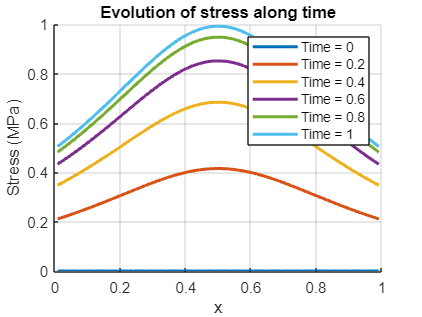

% Evolution of stresses along time
% --------------------------------------------
figure
hold on
xlabel('x')
ylabel('Stress (MPa)')
title('Evolution of stress along time')
COOR_gauss = (COOR(CN(:,2))+  COOR(CN(:,1)))/2 ;
nsteps_plot = length(stepsPOST) ;
hplot = zeros(nsteps_plot,1) ;
LegendPlot = cell(nsteps_plot,1) ;
for i = 1:nsteps_plot
    hplot(i) =  plot(COOR_gauss,STRESS_GLO(:,stepsPOST(i)),'LineWidth',2) ;
    %LegendPlot{i} = ['Time = ',num2str(TIMES(stepsPOST(i))),'; NELEM =',num2str(NELEM),'; NSTEP = ',num2str(nsteps)] ;
    LegendPlot{i} = ['Time = ',num2str(TIMES(stepsPOST(i)))] ;end
grid on
legend(hplot,LegendPlot)

legend('off')
legend

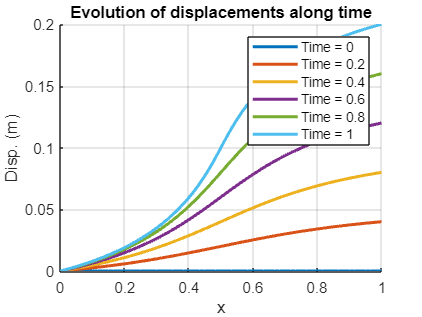


% Evolution of displacements along time
% --------------------------------------------
figure
hold on
xlabel('x')
ylabel('Disp. (m)')
title('Evolution of displacements along time')
nsteps_plot = length(stepsPOST) ;
hplot = zeros(nsteps_plot,1) ;
LegendPlot = cell(nsteps_plot,1) ;
for i = 1:nsteps_plot
    hplot(i) =  plot(COOR,d_GLO(:,stepsPOST(i)),'LineWidth',2) ;
   %LegendPlot{i} = ['Time = ',num2str(TIMES(stepsPOST(i))),'; NELEM =',num2str(NELEM),'; NSTEP = ',num2str(nsteps)] ;
    LegendPlot{i} = ['Time = ',num2str(TIMES(stepsPOST(i)))] ;

end
grid on
legend(hplot,LegendPlot)

legend('off')
legend

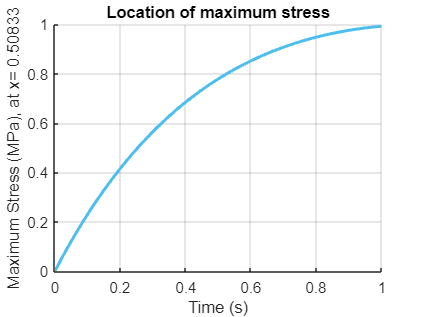




% Location of maximum stress

[stressEND,indELEM ]= max(STRESS_GLO(:,end)) ;
COOR_max_stress= COOR_gauss(indELEM) ;

figure
hold on
title('Location of maximum stress')
xlabel('Time (s)')
ylabel([['Maximum Stress (MPa), at x= ',num2str(COOR_max_stress)]]) ;
for i = 1:nsteps_plot
    h =   plot(TIMES,STRESS_GLO(indELEM,:),'LineWidth',2) ;
end
grid on

%legend(h,['NELEM =',num2str(NELEM),'; NSTEP = ',num2str(nsteps)])

%legend('off')
%legend
